clc;
clear;
close all;

%%%% getting path
% addpath(genpath('xytheta'));

% load('femm_output_sensor_r48_20220531_1937.mat')
load('femm_output_sensor_r48_20220623_1735.mat')

% a1a2a3a4 b1b2b3b4 c1c2c3c4
% too many figures

% for m = x_index
%     for n = 1:1:4
%         f(n,m) = figure; %a
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' a',num2str(n)])
%         f(n+4,m) = figure; %b
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' b',num2str(n)])
%         f(n+8,m) = figure; %c
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' c',num2str(n)])
%     end
% end
% 
% for m = x_index
%     for n = y_index
%         figure(f(1,m));
%         plot(theta_r_in,a1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(2,m));
%         plot(theta_r_in,b1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(3,m));
%         plot(theta_r_in,c1(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(4,m));
%         plot(theta_r_in,a2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(5,m));
%         plot(theta_r_in,b2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(6,m));
%         plot(theta_r_in,c2(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(7,m));
%         plot(theta_r_in,a3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(8,m));
%         plot(theta_r_in,b3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(9,m));
%         plot(theta_r_in,c3(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(10,m));
%         plot(theta_r_in,a4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(11,m));
%         plot(theta_r_in,b4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%         figure(f(12,m));
%         plot(theta_r_in,c4(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%     end
% end

max_peak_flux = zeros(length(x_index),length(y_index));
min_peak_flux = zeros(length(x_index),length(y_index));


for x = x_index
    for y = y_index
        max_arr = [max(abs(a1(:,x,y))),max(abs(a2(:,x,y))),max(abs(a3(:,x,y))),max(abs(a4(:,x,y))), ...
            max(abs(b1(:,x,y))),max(abs(b2(:,x,y))),max(abs(b3(:,x,y))),max(abs(b4(:,x,y))) ...
            ,max(abs(c1(:,x,y))),max(abs(c2(:,x,y))),max(abs(c3(:,x,y))),max(abs(c4(:,x,y)))];
        max_peak_flux(x,y) = max(max_arr);
        min_peak_flux(x,y) = min(max_arr);
        diff = a1(:,x,y)-a2(:,x,y);
    end
end

max_peak_flux'

ans =     0.0646    0.0635    0.0623    0.0612    0.0601    0.0612    0.0623    0.0634    0.0646
    0.0634    0.0615    0.0605    0.0594    0.0584    0.0594    0.0604    0.0615    0.0635
    0.0623    0.0605    0.0587    0.0577    0.0567    0.0577    0.0587    0.0605    0.0623
    0.0612    0.0594    0.0576    0.0560    0.0550    0.0560    0.0577    0.0594    0.0612
    0.0601    0.0584    0.0567    0.0551    0.0535    0.0550    0.0567    0.0584    0.0601
    0.0613    0.0594    0.0577    0.0560    0.0551    0.0560    0.0577    0.0594    0.0613
    0.0623    0.0605    0.0587    0.0577    0.0567    0.0577    0.0587    0.0605    0.0623
    0.0635    0.0615    0.0605    0.0594    0.0584    0.0594    0.0605    0.0615    0.0635
    0.0646    0.0635    0.0623    0.0613    0.0601    0.0613    0.0623    0.0635    0.0646


min_peak_flux'

ans =     0.0449    0.0455    0.0456    0.0456    0.0456    0.0456    0.0456    0.0455    0.0449
    0.0455    0.0469    0.0470    0.0470    0.0470    0.0470    0.0470    0.0469    0.0455
    0.0456    0.0470    0.0485    0.0485    0.0485    0.0485    0.0485    0.0470    0.0455
    0.0456    0.0470    0.0485    0.0501    0.0501    0.0501    0.0485    0.0470    0.0456
    0.0456    0.0470    0.0485    0.0501    0.0517    0.0501    0.0485    0.0470    0.0456
    0.0456    0.0470    0.0485    0.0501    0.0501    0.0501    0.0485    0.0470    0.0456
    0.0455    0.0470    0.0485    0.0485    0.0485    0.0485    0.0485    0.0470    0.0456
    0.0455    0.0469    0.0470    0.0470    0.0470    0.0470    0.0470    0.0469    0.0455
    0.0449    0.0455    0.0456    0.0456    0.0456    0.0456    0.0455    0.0455    0.0449


dif_max_flux =max_peak_flux'-min_peak_flux'

dif_max_flux =     0.0197    0.0180    0.0168    0.0157    0.0146    0.0156    0.0168    0.0179    0.0197
    0.0179    0.0147    0.0135    0.0124    0.0113    0.0124    0.0135    0.0147    0.0180
    0.0168    0.0135    0.0102    0.0092    0.0082    0.0092    0.0102    0.0135    0.0168
    0.0156    0.0124    0.0092    0.0059    0.0050    0.0059    0.0092    0.0124    0.0157
    0.0146    0.0114    0.0082    0.0050    0.0018    0.0050    0.0082    0.0114    0.0146
    0.0157    0.0124    0.0091    0.0060    0.0050    0.0059    0.0092    0.0124    0.0157
    0.0168    0.0135    0.0102    0.0091    0.0082    0.0092    0.0102    0.0135    0.0168
    0.0179    0.0147    0.0135    0.0124    0.0113    0.0124    0.0135    0.0147    0.0179
    0.0197    0.0180    0.0168    0.0157    0.0146    0.0157    0.0168    0.0179    0.0197


max_flux = max(max(max_peak_flux))

max_flux = 0.0646

min_flux = min(min(min_peak_flux))

min_flux = 0.0449


fine_x= find(max_peak_flux'*25-2.5 <0,1)

fine_x = 1

x_position(fine_x)

ans = -2

dq = 2/3*[1 -0.5 -0.5;0 sqrt(3)/2 -sqrt(3)/2;1/2 1/2 1/2]

dq =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774
    0.3333    0.3333    0.3333



alpha = zeros(4,length(theta_r_index),length(x_index),length(y_index));
beta = zeros(4,length(theta_r_index),length(x_index),length(y_index));
gamma = zeros(4,length(theta_r_index),length(x_index),length(y_index));
for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            alpha(1,r,x,y)=dq(1,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            alpha(2,r,x,y)=dq(1,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            alpha(3,r,x,y)=dq(1,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            alpha(4,r,x,y)=dq(1,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            beta(1,r,x,y)=dq(2,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            beta(2,r,x,y)=dq(2,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            beta(3,r,x,y)=dq(2,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            beta(4,r,x,y)=dq(2,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
            gamma(1,r,x,y)=dq(3,:)*[a1(r,x,y);b1(r,x,y);c1(r,x,y)];
            gamma(2,r,x,y)=dq(3,:)*[a2(r,x,y);b2(r,x,y);c2(r,x,y)];
            gamma(3,r,x,y)=dq(3,:)*[a3(r,x,y);b3(r,x,y);c3(r,x,y)];
            gamma(4,r,x,y)=dq(3,:)*[a4(r,x,y);b4(r,x,y);c4(r,x,y)];
        end
    end
end

x12 = zeros(length(theta_r_index),length(x_index),length(y_index));
y12 = zeros(length(theta_r_index),length(x_index),length(y_index));
x34 = zeros(length(theta_r_index),length(x_index),length(y_index));
y34 = zeros(length(theta_r_index),length(x_index),length(y_index));

xhat = zeros(length(theta_r_index),length(x_index),length(y_index));
yhat = zeros(length(theta_r_index),length(x_index),length(y_index));

for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            x12(r,x,y) = alpha(1,r,x,y)*gamma(1,r,x,y)-alpha(2,r,x,y)*gamma(2,r,x,y);
            y12(r,x,y) = beta(1,r,x,y)*gamma(1,r,x,y)-beta(2,r,x,y)*gamma(2,r,x,y);
            x34(r,x,y) = cos(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))-sin(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));
            y34(r,x,y) = sin(-pi/6)*(alpha(3,r,x,y)*gamma(3,r,x,y)-alpha(4,r,x,y)*gamma(4,r,x,y))+cos(-pi/6)*(beta(3,r,x,y)*gamma(3,r,x,y)-beta(4,r,x,y)*gamma(4,r,x,y));

        end
    end
end



%%kg calculation x=1, y=0 fixed point
    
    x_mid = median(x_index);
    y_mid = median(y_index);
    checkx1y0 = x12(:,x_mid+2,y_mid)+x34(:,x_mid+2,y_mid);
    x1y0 = [x_position(1,x_mid+2),y_position(1,y_mid)]

x1y0 =      1     0


    mean(checkx1y0);
    kg = round(norm(x1y0)/mean(checkx1y0))

kg = 3247


for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            xhat(r,x,y) = kg*(x12(r,x,y)+x34(r,x,y));
            yhat(r,x,y) = -kg*(y12(r,x,y)+y34(r,x,y));
        end
    end
end

%%theta calculation
theta1hat = zeros(length(theta_r_index),length(x_index),length(y_index));
theta2hat = zeros(length(theta_r_index),length(x_index),length(y_index));
theta_r_hat = zeros(length(theta_r_index),length(x_index),length(y_index));
for(r = theta_r_index)
    for(x = x_index)
        for(y = y_index)
            theta1hat(r,x,y) = atan2(beta(2,r,x,y),alpha(1,r,x,y));
            theta2hat(r,x,y) = atan2(beta(1,r,x,y),alpha(2,r,x,y));
            theta_r_hat(r,x,y) = (theta1hat(r,x,y)+theta2hat(r,x,y))/2;
        end
    end
end


% f2 = zeros(length(x_index),2);
% 
% for m = x_index
%         f2(m,1) = figure; %a
%         hold on;
%         legend("off")
%         legend("show",Location="best")
%         title(['xhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' mm'])
% %         f2(m,2) = figure;
% %         hold on;
% %         legend("off")
% %         legend("show",Location="best")
% %         title(['yhat ','x = ', num2str(x_position(1,m)),  '  sensor r=  ',num2str(sensor_r),' mm'])
%     for n = y_index
%         figure(f2(m,1));
%         plot(theta_r_in,xhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
% %         figure(f2(m,2));
% %         plot(theta_r_in,yhat(:,m,n),'DisplayName',['y = ',num2str(y_position(1,n))])
%     end
% end

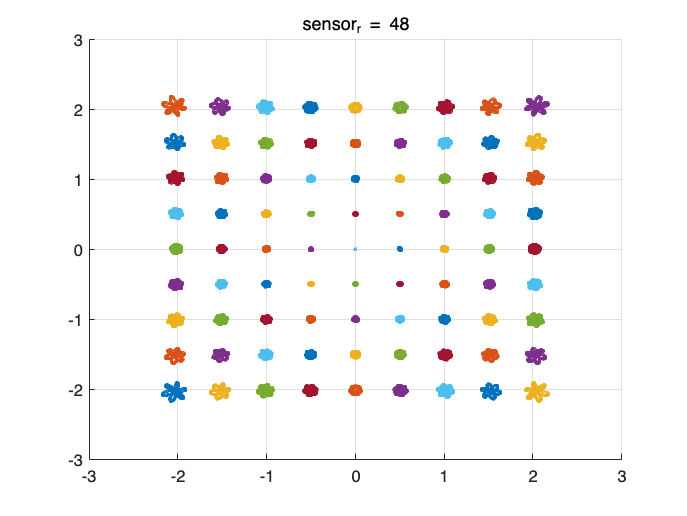

full_figure = figure;
hold on;
grid on;
title(['sensor_r = ',num2str(sensor_r)])
xlim([min(x_position)-1,max(x_position)+1])
ylim([min(y_position)-1,max(y_position)+1])
for m = x_index
    for n = y_index
        scatter(xhat(:,m,n),yhat(:,m,n),2)
    end
end


date = datestr(now,'yyyymmdd_HHMM')

date = '20220623_1753'

filename = sprintf('xytheta_output_sensor_r%d_kg%d_%s.mat',sensor_r,kg,date)

filename = 'xytheta_output_sensor_r48_kg3247_20220623_1753.mat'

save(filename)